% Arguments:
  xo=0;     % starting horizontal coordinate of the ray in meters
  zo=600;   % starting vertical coordinate of the ray in meters
  theta0=1; % starting angle of the ray in degrees
  tt=120;   % max travel time of the ray in seconds
%   zz:      vertical coordinates occf the sound speed profile (+ down)
%   cc:      sound speed measurements at zz locations
%   plotflag: Boolean flag for auto plotting result (optional) default is 0.
%
% Output:
%   xxf:       horizontal coordinates of the ray path
%   zzf:       vertical coordinates of the ray path
%   ttf:       actual travel time of the ray in seconds
%   ddf:       distance the ray traveled
%
% Raytrace will trace the path sound will travel through a medium with an
% isotropic horizontal sound speed profile and a vertical sound speed
% profile given by (zz,cc) from a point (xo,zo) and departing at an angle
% theta0 for a time of tt seconds. The path is returned in vectors x and z.
% The actual time of travel is returned in t, which may be slightly greater
% that tt. The sound speed profile should include a measurement at the
% surface (zz = 0). If it does not, the profile will be extended to the
% surface by replicating the first measurement there.

In addition to the above, raytrace() handles caustics (when rays bend through horizontal) and reflections off the surface (z=0) and bottom which is taken to be at the maximum depth measurement in the sound speed profile. The bottom is assumed to be flat. Reflections up to a maximum number (MAXBOUNCES) is supported. MAXBOUNCES is hard-coded into the function. Decreasing MAXBOUNCES will reduce the memory required for calculations when many reflections are not needed.

EXAMPLE:

Trace a ray for 120 seconds starting from 0 m depth at a 5 degree down angle through a sound speed profile that has a value of 1520 at the surface, decreases with a gradient of -0.05 m/s /m to 750 m, and then increases with a gradient of 0.014 m/s /m to a maximum depth of 5000 m.

Setup the sound speed profile

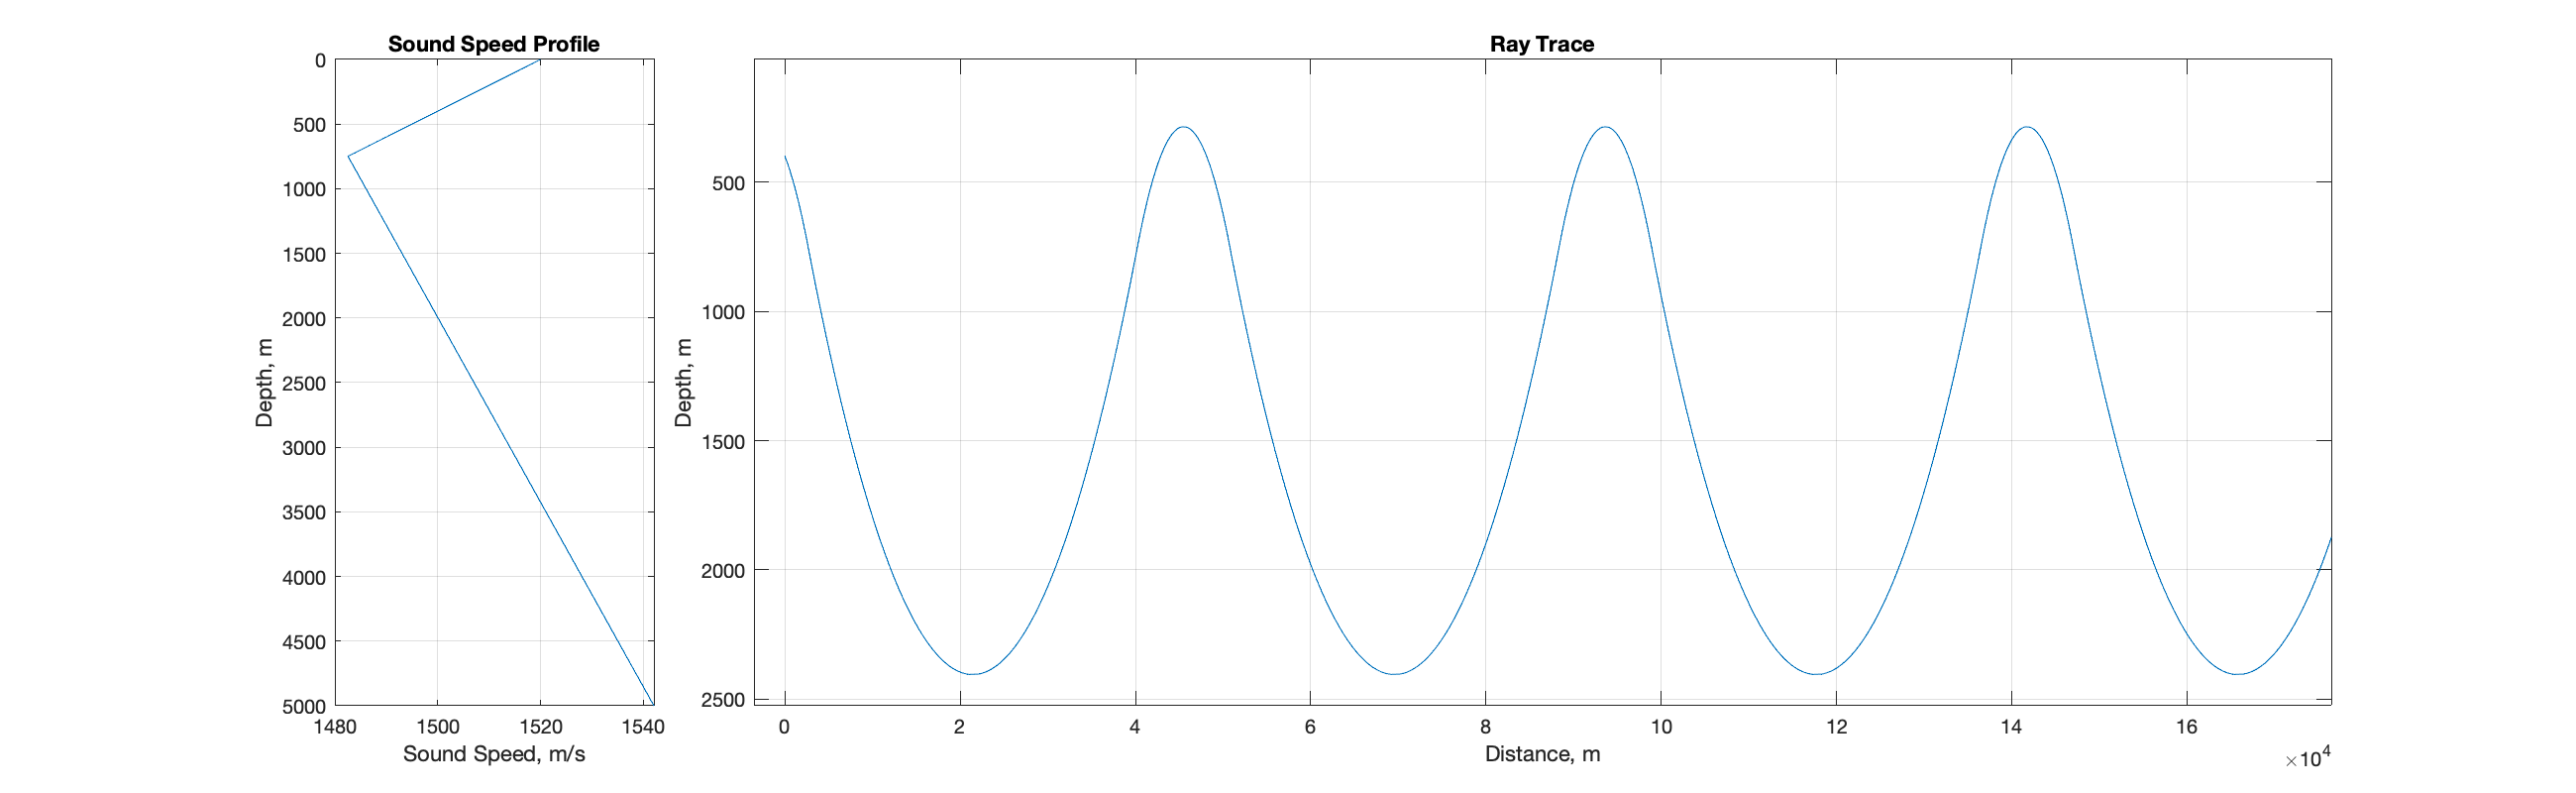

zz = 0:1:5000;
cc = 1520 + [zz*-.05];
cc(751:end) = cc(750) + (zz(751:end)-zz(750))*.014;
% % Conduct the raytrace and plot result
[x,z,t,d] = raytrace(xo,zo,theta0,120,zz,cc,true);